## 目的：建立以小波为特征的失稳监测模型

链接：[RI_Monitoring](https://github.com/jiaqiwang969/RI_Monitoring)

clc
clear
close all
addpath(genpath('subfunction'));
%% 保存图像至指定文件夹

save_directory = ['Result-',date];  %频谱图存储文件夹
if ~exist(save_directory)
    mkdir(save_directory)
else
    disp('文件夹存在！');
end

文件夹存在！


## 数据准备：

- 转速9000:16000rpm的压气机阀门开度逐渐减小到失速的过程采集；

- 包含10个传感器（B1、R1-R8、C1）；

- 通过数据的序号换算阀门开度；（不同转速换算公式不同，a/b）

%DataInfo:包含数据的位置、数据转速、数据序列、对应阀门开度、传感器位置等信息
DataInfo.RotorSpeed=[6000;6500;7000;7500;8000;8500;9000;9500;10000;10500;11000;11500;12000;12500;13000;14000;15000;16000];
DataInfo.famen_init=[100;100;100;100;100;100;100;100;100;100;100;100;100;100;100;75;75;75];
DataInfo.famen_end=[29;29;29;29;29;29;29;29;29;29;27;29;29;29;29;29;29;29];
DataInfo.famen_SI=[29;29;29;29;29;29;29;29;29;29;29;29;29;29;29;29;29;29];
DataInfo.xuhao_init=[1;1;1;1;1;1;1;1;1;1;1;1;1;1;1;1;1;1]

DataInfo = 包含以下字段的 struct :
    RotorSpeed: [18×1 double]
    famen_init: [18×1 double]
     famen_end: [18×1 double]
      famen_SI: [18×1 double]
    xuhao_init: [18×1 double]


DataInfo.xuhao_end=[92;94;95;93;95;95;98;95;93;94;98;94;97;93;92;68;77;76];
DataInfo.xuhao_SI=[92;94;95;93;95;95;95;95;93;94;94;93;94;92;92;68;77;76];
for k=1:length(DataInfo.RotorSpeed)
DataInfo.location{k,1}=['DATA','/','Compressor2Stall-',num2str(DataInfo.RotorSpeed(k))];
DataInfo.parameterLocation{k,1}=[DataInfo.location{k,1},'/','参数说明','/','parameter.mat'];
end

%目的：统一选择阀门开度范围（横坐标固定）
%计算阀门开度和序号的线性对应关系(famen=xuhao*a+b;)
DataInfo.a=(DataInfo.famen_end-DataInfo.famen_init)./(DataInfo.xuhao_end-DataInfo.xuhao_init);
DataInfo.b=DataInfo.famen_init-DataInfo.xuhao_init.*DataInfo.a;
DataInfo.sensorArray={'B1';'R1';'R2';'R3';'R4';'R5';'R6';'R7';'R8';'C1'};
DataInfo.label=75:-5:29;
DataInfo.xuhao=round((DataInfo.label-DataInfo.b)./DataInfo.a);
for k=1:length(DataInfo.label)
    DataInfo.labelName{k}=[num2str(DataInfo.label(k))];
end

## 数据处理Process

%基于DataInfo的数据处理集Process
%输入：转速、采样率等影响参数，分析阶次
RotorSpeed=16000;
resamplePoint=100;
label=find((DataInfo.RotorSpeed==RotorSpeed)==1);
Wavlet.fk=[1:1:100];
PI_level=1000;


% 导入数据

Process.sensorParameter=load([DataInfo.location{label},'/','参数说明','/','parameter.mat']); %选择文件导入数据
Process.loadMat=[];
for k=DataInfo.xuhao_init(label):DataInfo.xuhao_end(label)
    Process.loadMat{k} = ['Compressor2Stall-',num2str(RotorSpeed),'-',num2str(k),'.mat'];
end

Process.fsResample=round(resamplePoint*RotorSpeed/60/10)*10;
Process.dt = 1/Process.fsResample ;
Process.sst1=[]

Process = 包含以下字段的 struct :
    sensorParameter: [1×1 struct]
            loadMat: {1×76 cell}
         fsResample: 26670
                 dt: 3.7495e-05
               sst1: []


for  i_file=1:length(Process.loadMat)
    Process.DataBase=importdata(fullfile(DataInfo.location{label},char(Process.loadMat(i_file))));
    Process.DataBase=V2Pa(Process.DataBase,Process.sensorParameter.kulite_transform_ab);
    Process.sst1{i_file}=resample(Process.DataBase(:,1:end-1),Process.fsResample,Process.sensorParameter.fs);
end

% 降采样处理

## 小波变换

Wavlet.level=100;
Wavlet.pad = 0;                                   % 2次幂0填充
Wavlet.dj = 0.125;                                % this will do 4 sub-octaves per octave
Wavlet.s0 = 15*Process.dt;                                % this says start at a scale of 6 months
Wavlet.j1 = 200;                                  % this says do 7 powers-of-two with dj sub-octaves each
Wavlet.lag1 = 0.75;                               % lag-1 autocorrelation for red noise background
Wavlet.mother = 'morlet';
Wavlet.period=1./Wavlet.fk/(RotorSpeed/60);
% k0=6;fourier_factor = (4*pi)/(k0 + sqrt(2 + k0^2)); % Scale-->Fourier [Sec.3h]
Wavlet.fourier_factor=1.0330; %在'MORLET' this is k0 (wavenumber), default is 6.
Wavlet.scale=Wavlet.period/Wavlet.fourier_factor;
Wavlet.global_ws=[];
for  i_file=1:length(Process.loadMat)
    [Wavlet.wave,Wavlet.period,Wavlet.coi] = wavelet_10sensor(Process.sst1{i_file}(:,Process.sensorParameter.object(1:10)),Process.dt,Wavlet.pad,Wavlet.dj,Wavlet.mother,Wavlet.scale);
    Wavlet.power = (abs(Wavlet.wave)).^2/PI_level;        % compute wavelet power spectrum
    Wavlet.fk=1./Wavlet.period/(RotorSpeed/60);
    Wavlet.global_ws{1,i_file}=reshape(sum(Wavlet.power,2),length(Wavlet.period),10);
end


## RI频带的选择和不同位置的影响

- 如何选择最鲁棒的频带范围?

- 举例说明，最低和最高转速，解释频带选择需要考虑的因素。（加一个频带局部放大图）

sensorLabel=2;
%
xuhao_init=DataInfo.xuhao(label,1);
xuhao_end=DataInfo.xuhao(label,end);
jet_color=colormap(jet(xuhao_end-xuhao_init+1));
%
close all
h1=figure('Visible', 'on');
set(gca,'units','centimeters')
pos = get(gca,'Position');
ti = get(gca,'TightInset');

set(gcf, 'PaperUnits','centimeters');
set(gcf, 'PaperSize', [pos(3)+ti(1)+ti(3) pos(4)+ti(2)+ti(4)]);
set(gcf, 'PaperPositionMode', 'manual');
set(gcf, 'PaperPosition',[0 0 pos(3)+ti(1)+ti(3) pos(4)+ti(2)+ti(4)]);
% set(gcf,'outerposition',get(0,'screensize'));

subplot('position',[0.1 0.51 0.43 0.2])
%局部放大
for k=xuhao_init:xuhao_end
    plot(Wavlet.global_ws{k}(:,sensorLabel),'.-','LineWidth',1,'MarkerSize',10,'Color',jet_color(k-xuhao_init+1,:))
    hold on
end
set(gca,'FontSize',14);
grid on
xlim([8 22])
title('RI频带局部放大','FontSize',14)
hold off

fig=subplot('position',[0.1 0.11 0.45 0.33]);
for k=xuhao_init:xuhao_end
    plot(Wavlet.global_ws{k}(:,sensorLabel),'.-','LineWidth',1,'MarkerSize',1,'Color',jet_color(k-xuhao_init+1,:))
    hold on
end
maximum=max(Wavlet.global_ws{k}(:,sensorLabel));
colormap(gca,'jet')
ylabel({'$W(fk)(Pa^2/1000)$'},'interpreter','latex','FontSize',20);
xlabel({'阶次'},'FontSize',20);
xlim([0 40])
txt = {['转速',num2str(RotorSpeed),'rpm'],['采样率',num2str(resamplePoint),'点/圈'],['传感器位置',DataInfo.sensorArray{sensorLabel}]};
annotation('textbox',...
    [0.12 0.25 0.18 0.13],...
    'String',txt,...
    'FontSize',12,...
    'FontName','Arial',...
    'LineStyle','--',...
    'EdgeColor',[1 1 0],...
    'LineWidth',2,...
    'BackgroundColor',[0.9  0.9 0.9],...
    'Color',[0.84 0.16 0]);
set(gca,'FontSize',14);
hold off
colorbar(gca,'TickLabels',{'75%','65%','55%','45%','35%','25%'}); 
subplot('position',[0.68 0.11 0.29 0.6])
sensorLabel=[1:10];
% close all
%频带1: RI频带【10-22】
%频带2: 1BPF 【27-31】
band1=[10:20];
band2=[27:31];
xuhao_init=DataInfo.xuhao(label,1);
xuhao_end=DataInfo.xuhao(label,end);
for i_file=xuhao_init:xuhao_end
    PI1(i_file,:)=sum(Wavlet.global_ws{1,i_file}(band1,:));
    PI2(i_file,:)=sum(Wavlet.global_ws{1,i_file}(band2,:));
end



plot(PI1(xuhao_init:xuhao_end,10),'LineWidth',2,'Color','k')
hold on
plot(PI1(xuhao_init:xuhao_end,9),'LineWidth',2,'Color',[0.6350 0.0780 0.1840])
plot(PI1(xuhao_init:xuhao_end,8),'LineWidth',2,'Color',[0.4940 0.1840 0.5560])
plot(PI1(xuhao_init:xuhao_end,7),'LineWidth',2,'Color',[0.3010 0.7450 0.9330])
plot(PI1(xuhao_init:xuhao_end,6),'LineWidth',2,'Color',[96 96 96]/255)
plot(PI1(xuhao_init:xuhao_end,5),'LineWidth',2,'Color',[0.9290 0.6940 0.1250])
plot(PI1(xuhao_init:xuhao_end,4),'LineWidth',2,'Color','y')
plot(PI1(xuhao_init:xuhao_end,3),'LineWidth',2,'Color','b')
plot(PI1(xuhao_init:xuhao_end,2),'LineWidth',2,'Color','g')
plot(PI1(xuhao_init:xuhao_end,1),'LineWidth',2,'Color','r')
hold off

%添加虚线
line([DataInfo.xuhao_SI(label)-xuhao_init,DataInfo.xuhao_SI(label)-xuhao_init],[0,max(max(PI1))*1.2],'linestyle','--','Color','k');
ylim([[0,max(max(PI1))*1.2]]);
legend1 = legend('C1','R8','R7','R6','R5','R4','R3','R2','R1','B1','SI')

legend1 =   Legend (C1, R8, R7, R6, R5, R4, R3, R2, R1, B1, SI) - 属性:

         String: {'C1'  'R8'  'R7'  'R6'  'R5'  'R4'  'R3'  'R2'  'R1'  'B1'  'SI'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.8658 0.3810 0.0946 0.3095]
          Units: 'normalized'

  显示 所有属性


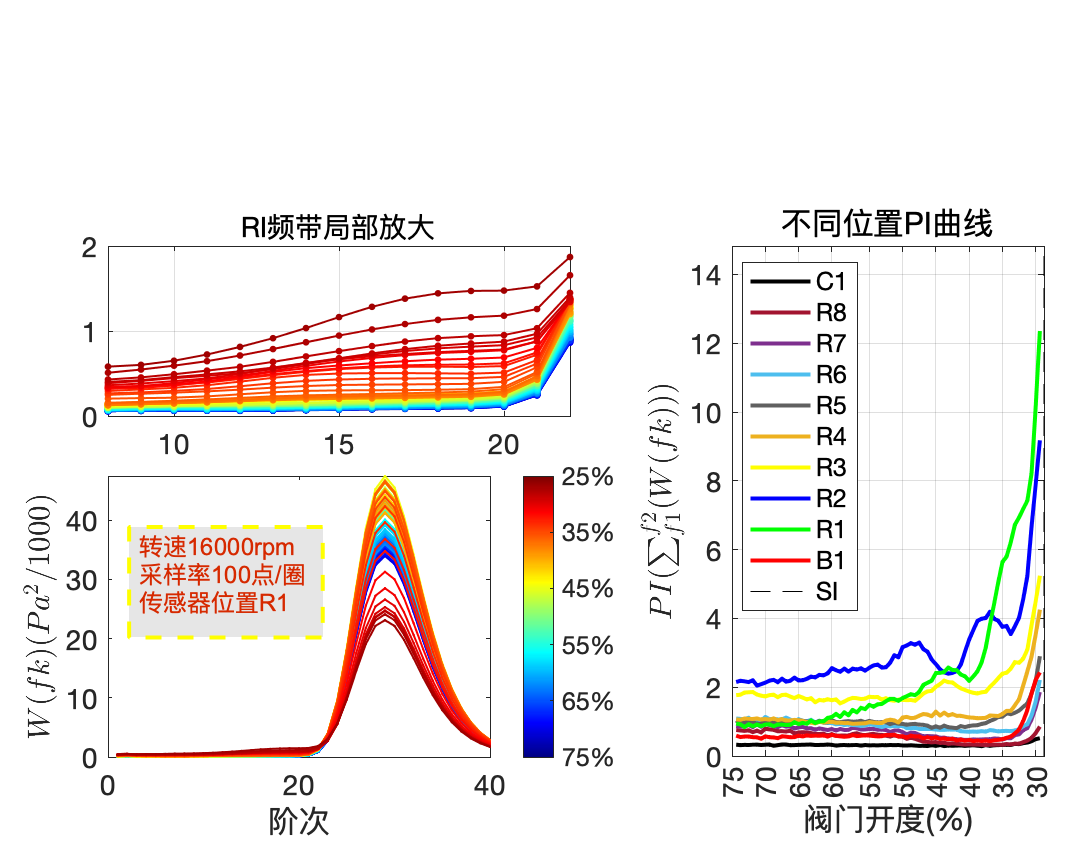

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


set(legend1,'NumColumns',1,'Location','northwest');
set(gca,'FontSize',14,'XGrid','on','XTick',DataInfo.xuhao(label,:)-xuhao_init,...
    'XTickLabel',DataInfo.labelName);
grid on
% 创建 ylabel
% ylabel({'PI（）'});
ylabel('$PI(\sum_{f1}^{f2}(W(fk)))$','interpreter','latex','FontSize',20)
% 创建 xlabel
xlabel('阀门开度(%)','FontSize',30);
% 设置其余坐标区属性
title('不同位置PI曲线','FontSize',14)
set(gca,'FontSize',14);
% ,'FontName','Songti'


saveas(h1,[save_directory,'/','FIG-转速',num2str(RotorSpeed),'rpm','-采样率',num2str(resamplePoint),'.png'])
saveas(h1,[save_directory,'/','FIG-转速',num2str(RotorSpeed),'rpm','-采样率',num2str(resamplePoint),'.fig'])
saveas(h1,[save_directory,'/','FIG-转速',num2str(RotorSpeed),'rpm','-采样率',num2str(resamplePoint),'.eps'])

% 
% set desired output size
set(h1, 'Units','centimeters')
height = 15;
width = 19;

% the last two parameters of 'Position' define the figure size
set(h1, 'Position',[25 5 width height],...
       'PaperSize',[width height],...
       'PaperPositionMode','auto',...
       'InvertHardcopy', 'off',...
       'Renderer','painters'...     %recommended if there are no alphamaps
   );
set(gcf, 'color', 'white');
saveas(h1,[save_directory,'/','FIG-转速',num2str(RotorSpeed),'rpm','-采样率',num2str(resamplePoint)],'pdf')

saveas(h1, [save_directory,'/','FIG-转速',num2str(RotorSpeed),'rpm','-采样率',num2str(resamplePoint),'.pdf']);

cleanfigure
matlab2tikz([save_directory,'/','FIG-转速',num2str(RotorSpeed),'rpm','-采样率',num2str(resamplePoint),'.tex']);

## 采样率的影响

## 转速的影响